##  Sequence Covariation

0.000000


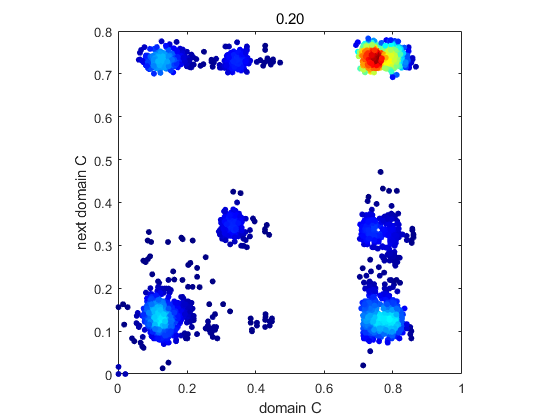

0.000000


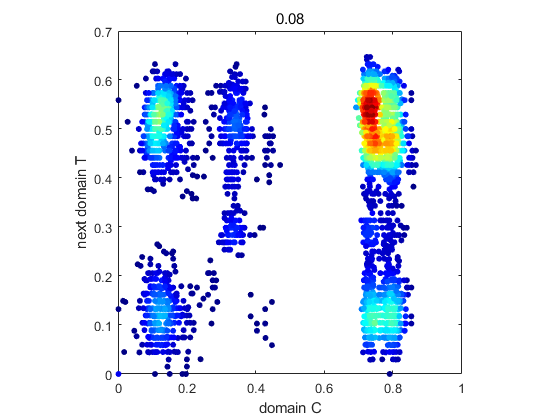

0.000000


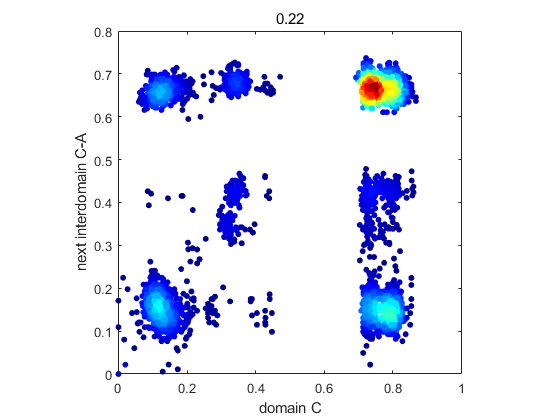

0.000000


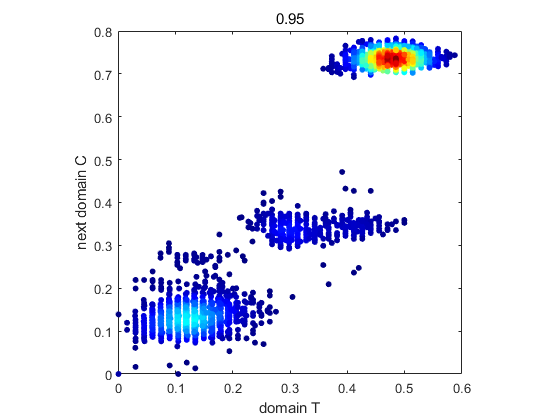

0.000000


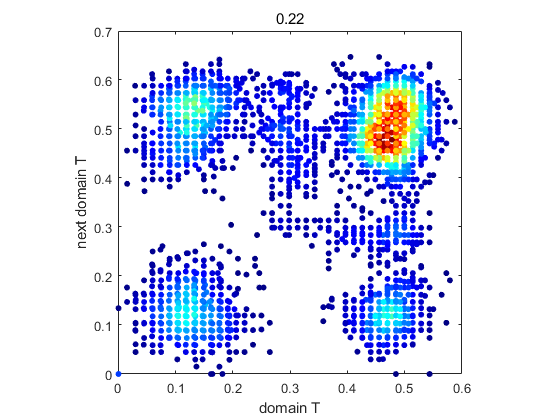

0.000000


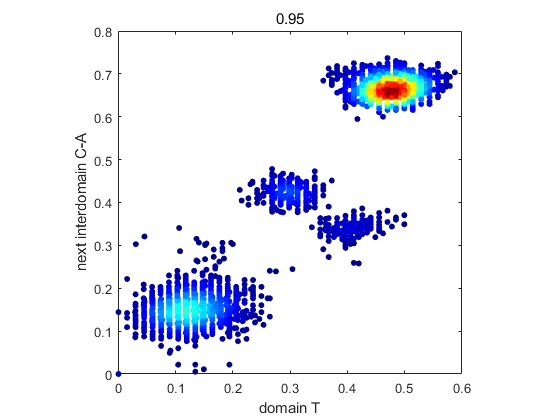

0.000000


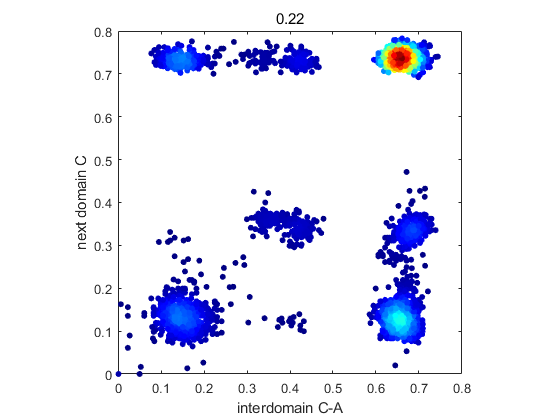

0.000000


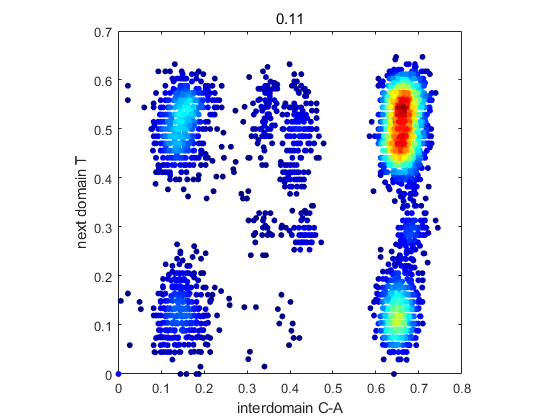

0.000000


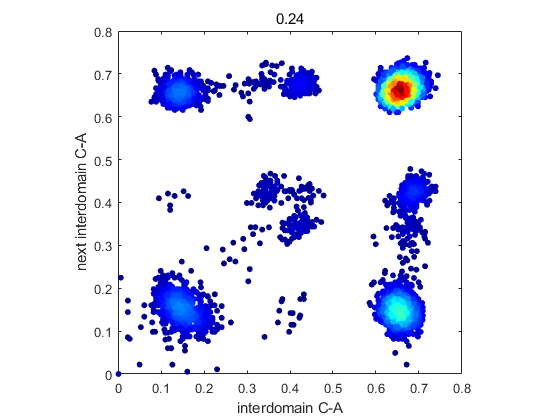


% construct "module distance" betwen all differnt omains: not same cluster: nan; same cluster: m(i,j)=m1-m2;
cEK_omains.modulediff_m=nan*zeros(cEK_omains.num,cEK_omains.num);
for c=1:cEK_regions.num
    o_thisc=find(cEK_omains.region_ids==c);
    for i=1:length(o_thisc)
        oi=o_thisc(i);
        for j=1:length(o_thisc)
            oj=o_thisc(j);
            cEK_omains.modulediff_m(oi,oj)=cEK_omains.moduleid(oi)-cEK_omains.moduleid(oj);
        end
    end
end

% for each pairs of omains, their within-same module and A-B(+1), B-A(+1) relationship
cEK_omains.standard_type=[Ctype,0;
    Atype,0;
    Ttype,0;
    Etype,0;
    TEtype,0;
    Ctype,Atype;
    Atype,Ttype;
    Ttype,Etype;
    Ttype,TEtype;
    Ttype,Ctype;
    Etype,Ctype;
    -1,Ctype;
    TEtype,-1;];

colorcodes_norm_8_dead=zeros(3,3,3);
colorcodes_norm_8_dead(1,1,:)=[0,1,0]; % normal-normal
colorcodes_norm_8_dead(2,2,:)=[1,0,0]; % 8-8
colorcodes_norm_8_dead(3,3,:)=[0,0,1]; % dead-dead

for i=1:3
    for j=(i+1):3
        colorcodes_norm_8_dead(i,j,:)=0.5*(colorcodes_norm_8_dead(i,i,:)+colorcodes_norm_8_dead(j,j,:));
        colorcodes_norm_8_dead(j,i,:)=colorcodes_norm_8_dead(i,j,:);
    end
end


colorbysurounding=1;
totestlist=[1,3,6];
for t1=totestlist%1:3%(size(cEK_omains.standard_type,1)-2)
    t1loc=find(ismember(cEK_omains.unitype_mat,cEK_omains.standard_type(t1,:),'rows'));
    diststruct_t1=cEK_omains.diststruct_bytype{t1loc};
    olist_t1=diststruct_t1.olist;
    did2loc_t1=diststruct_t1.did_2_loc;
    distm_aa_t1=diststruct_t1.distm_ntaa{2};
    
    if cEK_omains.standard_type(t1,2)==0
        t1_name=['domain ',cEK_omains.domaintypelist{cEK_omains.standard_type(t1,1)}];
    else
        t1_name=sprintf('interdomain %s-%s',cEK_omains.domaintypelist{cEK_omains.standard_type(t1,1)},cEK_omains.domaintypelist{cEK_omains.standard_type(t1,2)});
    end
    
    % whether to exclude the Dead clusters
    olist_t1=olist_t1(cEK_regions.fateid(cEK_omains.region_ids(olist_t1))>0);
    
    for t2=totestlist%(size(cEK_omains.standard_type,1)-2)
        t2loc=find(ismember(cEK_omains.unitype_mat,cEK_omains.standard_type(t2,:),'rows'));
        
        diststruct_t2=cEK_omains.diststruct_bytype{t2loc};
        olist_t2=diststruct_t2.olist;
        
        did2loc_t2=diststruct_t2.did_2_loc;
        distm_aa_t2=diststruct_t2.distm_ntaa{2};
        
        
        if cEK_omains.standard_type(t2,2)==0
            t2_name=['domain ',cEK_omains.domaintypelist{cEK_omains.standard_type(t2,1)}];
        else
            t2_name=sprintf('interdomain %s-%s',cEK_omains.domaintypelist{cEK_omains.standard_type(t2,1)},cEK_omains.domaintypelist{cEK_omains.standard_type(t2,2)});
        end
        
        for modulediff=-1%-1%[0,-1]
            %if modulediff==0 && t1>t2 % same module, needs to be different unit
            % find pair of t2s that are of the same module as t1
            
            paired_t2=0*olist_t1;
            touselist=[];
            if (modulediff==0 && t1>t2) || (modulediff==-1)
                for i=1:length(olist_t1)
                    o1=olist_t1(i);
                    pairo2=olist_t2(cEK_omains.modulediff_m(o1,olist_t2)==modulediff);
                    if ~isempty(pairo2)
                        paired_t2(i)=min(pairo2);
                        touselist=[touselist,i];
                    end
                end
            end
            if modulediff==-1
                t2_name=['next ',t2_name];
            end
            
            if length(touselist)>10
                
                
                locs1=did2loc_t1(olist_t1(touselist));
                locs2=did2loc_t2(paired_t2(touselist));
                part_distm_t1=distm_aa_t1(locs1,locs1);
                part_distm_t2=distm_aa_t2(locs2,locs2);
                
                v1=part_distm_t1(:);
                v2=part_distm_t2(:);
                [corrm,corrp]=corrcoef(v1,v2);
                
                index_m=reshape(1:length(v1),length(locs1),length(locs1));
                
                figure;
                
                
                if colorbysurounding
                    % color by Number of surroundings
                    
                    % first, for each dot, calculate the local "density"
                    x=v1;
                    y=v2;
                    dens=0*x;
                    r = sqrt((range(x)/30)^2 + (range(y)/30)^2);
                    for k=1:length(x)
                        dens(k) = sum( sqrt((x-x(k)).^2 + (y-y(k)).^2) < r );
                    end
                    
                    
                    
                    dotcolor=dens;
                    
                    dotalpha=1;
                    colormap('jet')
                else
                    % set colors
                    dotcolor=zeros(length(v1),3);
                    % color by group: with C8, or other dead clusters
                    % which ones has to do with C8
                    locs_8=find(cEK_omains.region_ids(olist_t1(touselist))==8);
                    index_8s=unique([index_m(locs_8,:),index_m(:,locs_8)']);
                    dotcolor(index_8s,:)=repmat([1,0,0],length(index_8s),1);
                    
                    % which ones has to do with dead clusters
                    locs_dead=find(cEK_regions.fateid(cEK_omains.region_ids(olist_t1(touselist)))==0);
                    index_deads=unique([index_m(locs_dead,:),index_m(:,locs_dead)']);
                    dotcolor(index_deads,:)=repmat([0,0,0],length(index_deads),1);
                    dotalpha=0.2;
                end
                
                
                
                ms=20;
                if modulediff==0
                    scatter(v2,v1,ms,dotcolor,'filled','MarkerEdgeColor','none','MarkerFaceAlpha',dotalpha)
                    %colorbar;
                    xlabel(t2_name)
                    ylabel(t1_name)
                    else
                    
                    scatter(v1,v2,ms,dotcolor,'filled','MarkerEdgeColor','none','MarkerFaceAlpha',dotalpha)
                    %colorbar;
                    xlabel(t1_name)
                    ylabel(t2_name)
                end
            
                box on;
                title(sprintf('%0.2f',corrm(1,2)))
                fprintf('%f\n',corrp(1,2));
                axis square
                %axis([0 1 0 1])
            end
            
            %else % modulediff==0 && t1>t2
            %end % modulediff==0 && t1>t2
        end
    end
end

## T domain alignment: the chirality unit

first, it is the multiple sequence alignment of T

touserlist=find(cEK_regions.fateid>0)%;goodcEKrlist;

touserlist =      1
     3
     5
     6
     8
    10
    11
    12
    13
    14


Tdomains=find(cEK_omains.typeid_mat(:,1)==Ttype & cEK_omains.isdomain==1 & ismember(cEK_omains.region_ids,touserlist));


% add information for the cEK_omains.subtypestr
% T domain: if it is followed by an E domain, or at the end
for t=1:length(Tdomains)
    tdid=Tdomains(t);
    nextd=tdid+2;
    ts_thisc=Tdomains(cEK_omains.region_ids(tdid)==cEK_omains.region_ids(Tdomains));
    %if nextd>cEK_omains.num || cEK_omains.region_ids(nextd)~=cEK_omains.region_ids(tdid) || cEK_omains.typeid_mat(nextd,1)==TEtype || cEK_omains.typeid_mat(nextd,1)==-1
    %    cEK_omains.subtypestr{tdid}='T_End';
    
    if cEK_omains.typeid_mat(nextd,1)==Etype
        cEK_omains.subtypestr{tdid}='T_Dtype';
    elseif tdid==max(ts_thisc)% it is the last T of the cluster
        cEK_omains.subtypestr{tdid}='T_End';
    else % L type
        cEK_omains.subtypestr{tdid}='T_Ltype';
    end
end

% obtain following domains 
followingtypes=[Ctype,0;
    Ctype,Atype];
followingdomains=[Tdomains,Tdomains]*0;
followingtitle={'C domain','CA inter'};
for k=1:size(followingtypes,1) % C and CA
    
    typetocheck=followingtypes(k,:);
    
    nextomains=find(ismember(cEK_omains.typeid_mat,typetocheck,'rows') & ismember(cEK_omains.region_ids,touserlist));
    

    % order C by the T, with Cs ~ Tend
    oorderbyT=0*Tdomains;
    for i=1:length(Tdomains)
        T_did=Tdomains(i);
       
        pairo2=nextomains(cEK_omains.modulediff_m(T_did,nextomains)==-1);
        if isempty(pairo2) 
            if strcmp(cEK_omains.subtypestr{T_did},'T_End')
                % there is no C next, its an end T, find the first C
                thisregion_Cs=nextomains(cEK_omains.region_ids(nextomains)==cEK_omains.region_ids(T_did));
                pairo2=min(thisregion_Cs);
            else
                pairo2=nan;
            end
        end
        if isempty(pairo2) 
            pairo2=nan;
        end
        followingdomains(i,k)=pairo2;
    end
end

todel=find(isnan(sum(followingdomains,2)));
Tdomains(todel)=[];
followingdomains(todel,:)=[];

fprintf('Used %d\t T domains',length(Tdomains))

Used 100	 T domains

ans =    100   100


ans =    100     1


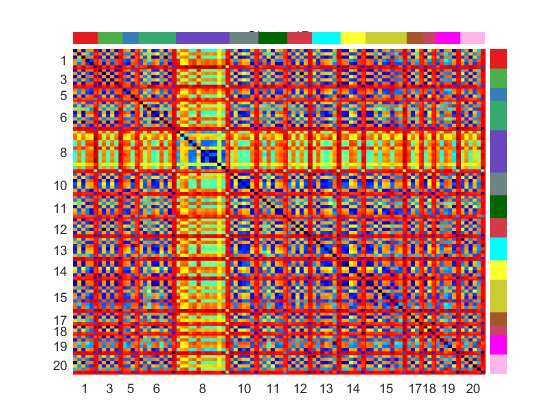

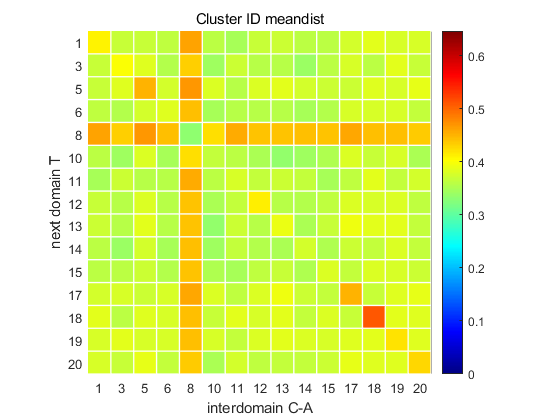

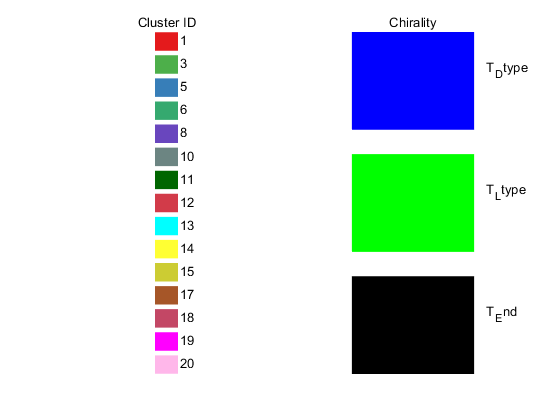

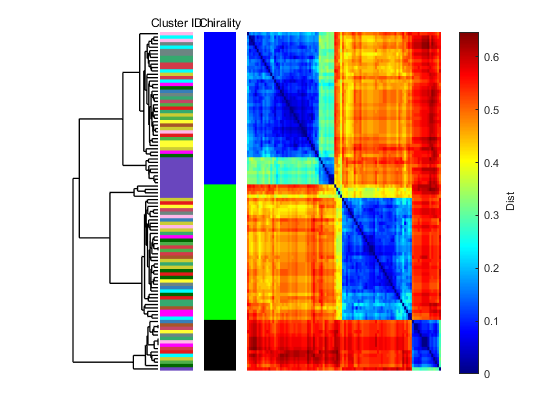

ans =    100   100


ans =    100     1


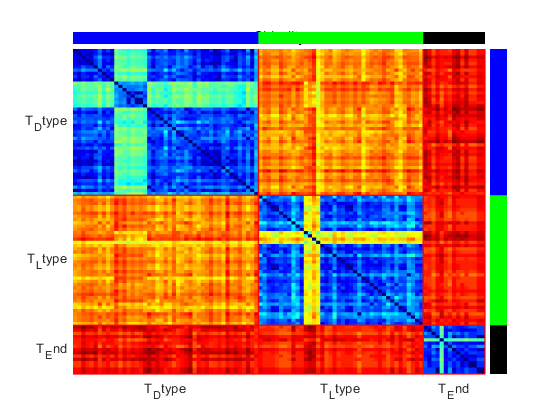


% load T domain distance
locindist=find(ismember(cEK_omains.unitype_mat,[Ttype,0],'rows'));

% extract distance structure of T
dist_olist=omains.diststruct_bytype{locindist}.olist;
dist_did2loc=omains.diststruct_bytype{locindist}.did_2_loc;
dist_distm=omains.diststruct_bytype{locindist}.distm_ntaa{2};

% perform multi alignment for T
T_phytree = seqlinkage(dist_distm(dist_did2loc(Tdomains),dist_did2loc(Tdomains)),'average');
seq_to_align=cEK_omains.seq_ntaa(Tdomains,2);
T_ma = multialign(seq_to_align,T_phytree,'ScoringMatrix','BLOSUM62');

% cluster the distance
figure;
colormap('parula')

g1=[];
g1.ids=cEK_omains.region_ids(Tdomains);
g1.id_2_name=strsplit(num2str(1:cEK_regions.num));
g1.id_2_color=cEK_regions.cluster_colors;
g1.name='Cluster ID';

deadclusters=find(cEK_regions.fateid==0);
if all(ismember(deadclusters, touserlist))
    g1.id_2_color(deadclusters,:)=cbrewer('qual','Paired',length(deadclusters));
end


g2=[];
[g2.id_2_name,~,g2.ids]=unique(cEK_omains.subtypestr(Tdomains));
g2.id_2_color=[0,0,1;
    0,0,0;
    0,1,0];
g2.name='Chirality';

groups={g1,g2};

    
cmin=0;
cmax=0.8;
[fhandles,optleafOrder]=DistMatrix_Analysis_HRL(dist_distm(dist_did2loc(Tdomains),dist_did2loc(Tdomains)),{'phytree_average'},groups);

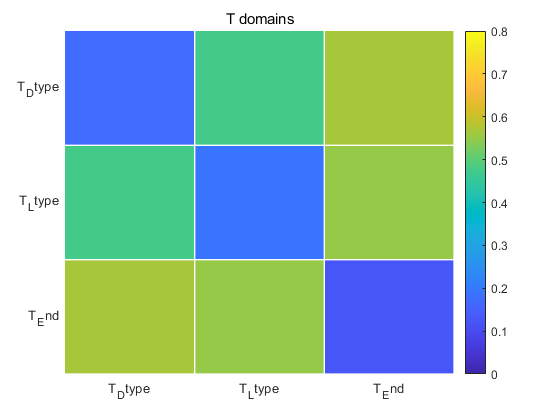

caxis([cmin,cmax])
title('T domains')

titlestr = 'T domain'

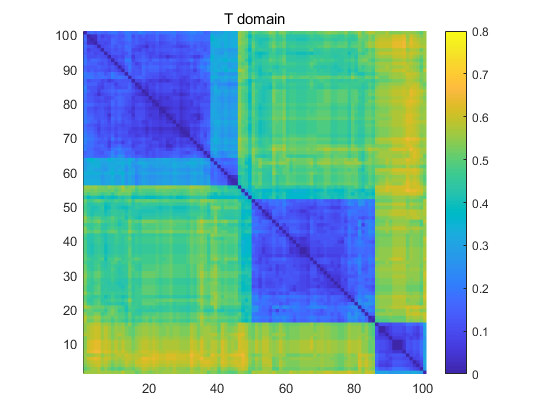

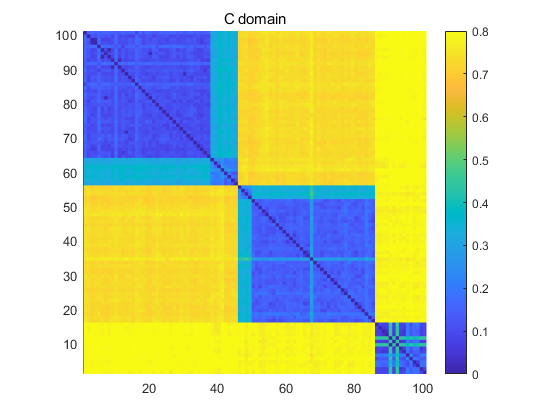

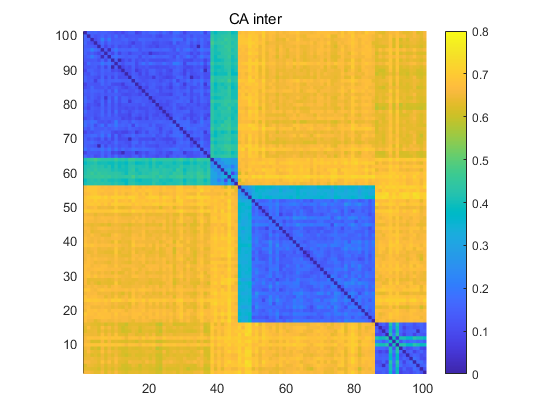



% use the same order for ordering for C and CA domain distance
% T distance again
  
    
for k=0:1:2 % C and CA
    if k~=0 % k==0: T
        typetocheck=followingtypes(k,:);
        locindist=find(ismember(cEK_omains.unitype_mat,typetocheck,'rows'));
       
        % extract distance
        dist_olist=omains.diststruct_bytype{locindist}.olist;
        dist_did2loc=omains.diststruct_bytype{locindist}.did_2_loc;
        dist_distm=omains.diststruct_bytype{locindist}.distm_ntaa{2};
        titlestr=followingtitle{k};
        listindist=dist_did2loc(followingdomains(optleafOrder,k));
        
        deadlabels=[];
        for i=1:length(Tdomains)
            oid=followingdomains(optleafOrder(i),k);
            deadlabels{length(Tdomains)-i+1}=[num2str(cEK_omains.region_ids(oid)),'-',num2str(cEK_omains.moduleid(oid))];
        end
    else
        titlestr='T domain'
        listindist=dist_did2loc(Tdomains(optleafOrder));
        
         deadlabels=[];
        for i=1:length(Tdomains)
            oid=Tdomains(optleafOrder(i));
            deadlabels{length(Tdomains)-i+1}=[num2str(cEK_omains.region_ids(oid)),'-',num2str(cEK_omains.moduleid(oid))];
        end
    
    end
    
    
    figure;
    colormap('parula')
    
    Easypcolor_flip_LZY(dist_distm(listindist,listindist),'u');
    colorbar off
    title(titlestr)
    
    if all(ismember(deadclusters, touserlist))
    axis on
    yticks(0.5+(1:length(Tdomains)))
    yticklabels(deadlabels)
    xticks([])
    end

    axis square
    caxis([cmin,cmax])
    
    colorbar
end

% use the same gap threshold for all
gapthresh=0.2;


% the mutal inforamtion between T and chirality
gappercent=sum(T_ma=='-')./size(T_ma,1);
column_to_keep=find(gappercent<gapthresh);




[condiH_eachsite,totalH,meandist_eachsite]=ZL_MotifbyConveration(T_ma(:,column_to_keep),'aa',[],0);
% mutual inforamtion with chirality
[unistr,~,chirality_subtype]=unique(cEK_omains.subtypestr(Tdomains));
T_ma_num=aa2int(T_ma(:,column_to_keep));
mulinfor_eachsite=0*meandist_eachsite;
for s=1:length(column_to_keep)
    [H1,H2,CH1_given2,CH2_given1,mulin]=ZL_Mulinfor_int(T_ma_num(:,s),chirality_subtype);
    mulinfor_eachsite(s)=mulin;
end
colortable=flipud(colormap('parula'));

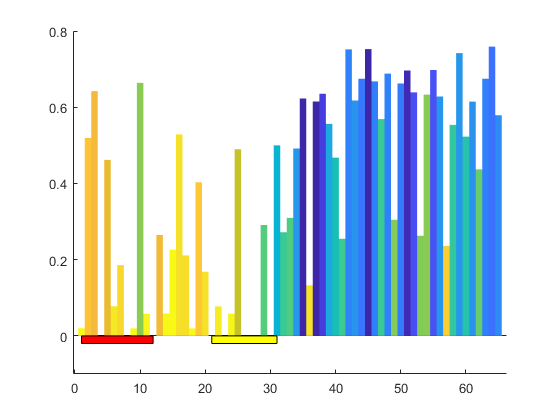

colornum=size(colortable,1);
mulinfor_colorid=max(1,min(colornum,round(colornum*(mulinfor_eachsite-min(mulinfor_eachsite))/(max(mulinfor_eachsite)-min(mulinfor_eachsite)))));



% plot out
figure;
hold on;
for i=1:length(meandist_eachsite)
    bh=bar(i,meandist_eachsite(i),1);
    bh.EdgeColor='none';
    bh.FaceColor=colortable(mulinfor_colorid(i),:);
end


Talpha_motif='EEALAAIWAEVL';
T1motif='DDFFELGGHSL';
CSeq_T = seqconsensus(T_ma(:,column_to_keep));

AlignStruct1 = localalign(CSeq_T,Talpha_motif);
AlignStruct2= localalign(CSeq_T,T1motif);


motifs_se_toshow=[AlignStruct1.Start(1,1),AlignStruct1.Stop(1,1);
    AlignStruct2.Start(1,1),AlignStruct2.Stop(1,1)];

lw=5;
colors=[1,0,0;
    cEK_omains.colorcode(Ttype,:)];
for i=1:size(motifs_se_toshow,1)
    ph=patch([motifs_se_toshow(i,1),motifs_se_toshow(i,2),motifs_se_toshow(i,2),motifs_se_toshow(i,1)],[0,0,-1,-1]*0.02,colors(i,:));
    ph.EdgeColor='k';
end
ylim([-0.1,0.8])
yticks(0:0.2:1)

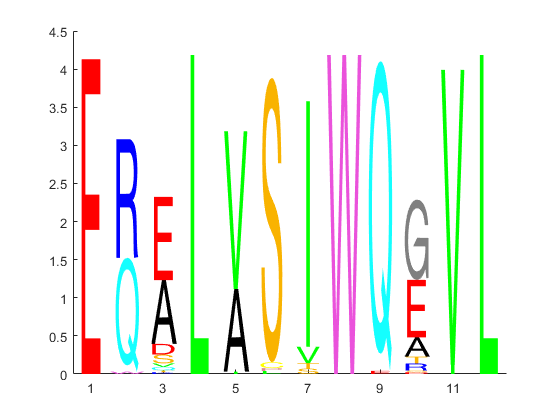

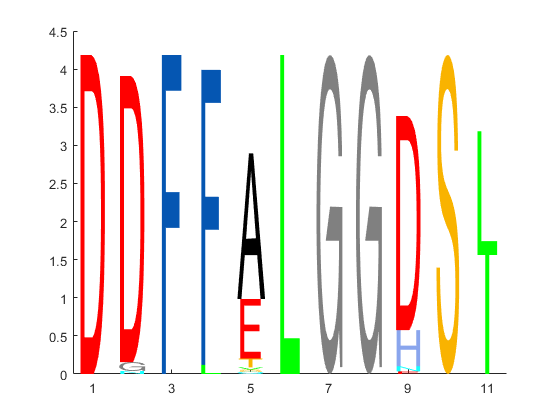


for i=1:size(motifs_se_toshow,1)
    figure;
    sp=motifs_se_toshow(i,1);
    ep=motifs_se_toshow(i,2);
    SeqLogo_HRL(T_ma(:,column_to_keep(sp:ep)),'aa',aa_colormaping,letterclass,0);
    xticks(1:2:(ep-sp+1));
    % set(gca,'xticklabel')
    xlim([0.5,(ep-sp+1.5)])
end

Then disect it by the motif:

A10-T1

T1-C1

T1-E1

T1-start of TE

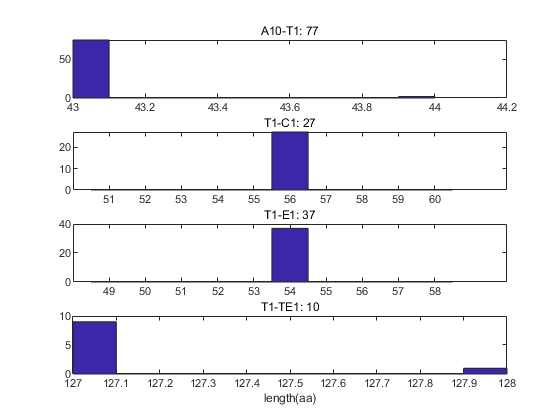

% in good region, only after A10-T1
A10_T1=find(ismember(motif_struct.region_id,goodcEKrlist) & ismember(motif_struct.motifid_mat_list,[Ttype,0.5],'rows') & motif_struct.motif_type_before==find(ismember(motif_struct.uni_motifids,[Atype,10],'rows')));


T1_C1=find(ismember(motif_struct.region_id,goodcEKrlist) & ismember(motif_struct.motifid_mat_list,[Ctype,0.5],'rows') & motif_struct.motif_type_before==find(ismember(motif_struct.uni_motifids,[Ttype,1],'rows')));


T1_E1=find(ismember(motif_struct.region_id,goodcEKrlist) & ismember(motif_struct.motifid_mat_list,[Etype,0.5],'rows') & motif_struct.motif_type_before==find(ismember(motif_struct.uni_motifids,[Ttype,1],'rows')));


T1_TE1=find(ismember(motif_struct.region_id,goodcEKrlist) & ismember(motif_struct.motifid_mat_list,[TEtype,0.5],'rows') & motif_struct.motif_type_before==find(ismember(motif_struct.uni_motifids,[Ttype,1],'rows')));


%
figure;
subplot(4,1,1)
hist(motif_struct.seqlen_aa(A10_T1));title(['A10-T1: ',num2str(length(A10_T1))]);
subplot(4,1,2)
hist(motif_struct.seqlen_aa(T1_C1));title(['T1-C1: ',num2str(length(T1_C1))]);
subplot(4,1,3)
hist(motif_struct.seqlen_aa(T1_E1));title(['T1-E1: ',num2str(length(T1_E1))]);
subplot(4,1,4)
hist(motif_struct.seqlen_aa(T1_TE1));title(['T1-TE1: ',num2str(length(T1_TE1))]);
xlabel('length(aa)');

## The whole C1-A1 region: alignment, chirality information, and new motifs

motif by motif, or ?

progresslist=(1:0.5:10)';
combined_types=[[Ctype*ones(size(progresslist)),progresslist];
    Atype,0.5;
    Atype,1];

dtype=Ctype;
mlist_firstmotif=find(ismember(motif_struct.region_id,goodcEKrlist) & ismember(motif_struct.motifid_mat_list,[dtype,1],'rows'));
loc_firstmotif=find(ismember(combined_types,[dtype,1],'rows'));
motif_mats=zeros(length(mlist_firstmotif),size(combined_types,1)); % all motifs related to this one
badmlist=[];
for i=1:length(mlist_firstmotif)
    for j=1:size(combined_types,1)
        shouldbe_mid = mlist_firstmotif(i)+j-loc_firstmotif;
        if ismember(motif_struct.motifid_mat_list(shouldbe_mid,:),combined_types(j,:),'rows')
            motif_mats(i,j)=shouldbe_mid;
        else
            badmlist(end+1)=i;
        end
    end
end %for i=1:length(m_list)
motif_mats(badmlist,:)=[];


second_olist=motif_struct.omains_id(motif_mats(:,2));
[~,~,mat_specificity]=unique(omains.subtypestr(second_olist));

lastlen=1;

motifid_mdist_mul_gap=[]; % alone the whole
tot_msa=[];
for m=1:size(motif_mats,2)
    m_mat=motif_mats(:,m);
    
    thism_type=combined_types(m,:);
    
    motifloc=find(ismember(motif_struct.uni_motifids,thism_type,'rows'));
    diststruct_mlist=motif_struct.motif_diststruct{motifloc}.mlist;
    diststruct_olist=motif_struct.motif_diststruct{motifloc}.olist;
    diststruct_distm=squareform(motif_struct.motif_diststruct{motifloc}.distline);
    diststruct_msa=motif_struct.motif_diststruct{motifloc}.msa;
    
    
     % only extract these in "good regions"
    diststruct_list_2_use=nan*zeros(size(m_mat));
    for i=1:length(diststruct_list_2_use) % hereya
        loc=find(diststruct_mlist==m_mat(i));
        if ~isempty(loc)
            diststruct_list_2_use(i)=loc;  % hereya   
        else
            error('seq not here');
        end
        diststruct_list_2_use(i)=loc;
    end % hereya
    
    % identity and length
    meanlen_toadd=mean(motif_struct.seqlen_aa(diststruct_mlist(diststruct_list_2_use)));
    
    %%%%% obtain mutual informations
    % calculate mutual information
    m_specificity=mat_specificity;%(loc_in_mmat);% hereya
    msa=diststruct_msa(diststruct_list_2_use,:);% hereya
    nanpercent=sum(msa=='-',1)/size(msa,1);
    
    %[value,order]=sort(nanpercent);nanthresh=max(0.5,value(ceil(meanlen_toadd)));
    %msa=msa(:,nanpercent<nanthresh);
    
    msa_num=aa2int(msa);
    msa_num(msa=='-'|msa=='*')=nan;
    
    %  fprintf('%f\t%f\t%f\n',nanthresh,size(msa,2),meanlen_toadd)
    
    mulinfor_list=zeros(1,size(msa_num,2));
    for s=1:size(msa_num,2)
        nonzerolist=find(m_specificity>0);
        
        [H1,H2,CH1_given2,CH2_given1,mulin]=ZL_Mulinfor_int(msa_num(nonzerolist,s),m_specificity(nonzerolist));
        mulinfor_list(s)=mulin;
    end
    
    [condiH_eachsite,totalH,meandist_eachsite]=ZL_MotifbyConveration(msa,'aa',[],0);
    
    
    addeddata=[m*ones(size(mulinfor_list));
        meandist_eachsite;
        mulinfor_list;
        nanpercent];
    motifid_mdist_mul_gap=[motifid_mdist_mul_gap,addeddata];
    
    
    tot_msa=[tot_msa,msa];
    
    
    lastlen=lastlen+meanlen_toadd;
end

figure;
hold on;
column_to_keep=find(motifid_mdist_mul_gap(end,:)<gapthresh);

% assign color
mulinfor_eachsite=motifid_mdist_mul_gap(3,column_to_keep);
colortable=flipud(colormap('parula'));
colornum=size(colortable,1);
mulinfor_colorid=max(1,min(colornum,round(colornum*(mulinfor_eachsite-min(mulinfor_eachsite))/(max(mulinfor_eachsite)-min(mulinfor_eachsite)))));

for i=1:length(column_to_keep)
    posi=column_to_keep(i);
    bh=bar(i,motifid_mdist_mul_gap(2,posi),1);
     bh.EdgeColor='none';
    bh.FaceColor=colortable(mulinfor_colorid(i),:);
end

% mark positions for motifs
for i=1:size(combined_types,1)
    mtype=combined_types(i,:);
    if abs(mtype(2)-round(mtype(2)))<0.1 && ~ismember(mtype(2),[5,6,10])
        locs=find(motifid_mdist_mul_gap(1,column_to_keep)==i);
        
        if i<20
             colorcode=cEK_omains.colorcode(Ctype,:);
             if mtype(2)>4
                 mid=mtype(2)-2;
             else
                 mid=mtype(2);
             end
            textstr=['C',num2str(mid)];
        else
         colorcode=cEK_omains.colorcode(Atype,:);  
         textstr=['A',num2str(mtype(2))];
        end
        ph=patch([locs(1),locs(end),locs(end),locs(1)],[0,0,-1,-1]*0.02,colorcode);
        ph.EdgeColor='k';
        text((locs(1)),-0.05,textstr)
        
    end
end
ylim([-0.1,0.8]);
yticks(0:0.2:1)


CSeq_CA = seqconsensus(tot_msa(:,column_to_keep));
CAmotif='ELLETFNHTEVAYP'

CAmotif = 'ELLETFNHTEVAYP'

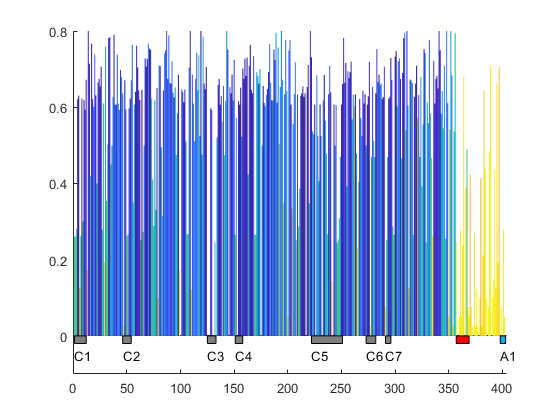

AlignStruct = localalign(CSeq_CA, CAmotif);

CAposi=AlignStruct.Start(1,1):AlignStruct.Stop(1,1);%437:450;'ELLETFNHTEVAYPRD'

hold on;
locs=CAposi;
colorcode=[1,0,0];
 ph=patch([locs(1),locs(end),locs(end),locs(1)],[0,0,-1,-1]*0.02,colorcode);

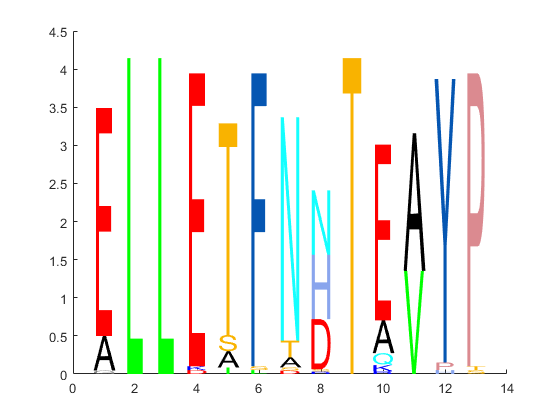

ph.EdgeColor='k';


figure;
SeqLogo_HRL(tot_msa(:,column_to_keep(CAposi)),'aa',aa_colormaping,letterclass,0);


% output the Position of CA motif to C7 and A1
 mtype=[Ctype,7];
 mlocintype=find(ismember(combined_types,mtype,'rows'));
 C7posi=find(motifid_mdist_mul_gap(1,column_to_keep)==mlocintype);
 
  
 mtype=[Atype,1];
 mlocintype=find(ismember(combined_types,mtype,'rows'));
 A1posi=find(motifid_mdist_mul_gap(1,column_to_keep)==mlocintype);
 
 
seqlines{1}=tot_msa(:,column_to_keep((C7posi(end)+1):(CAposi(1)-1)));
seqlines{2}=tot_msa(:,column_to_keep((CAposi(end)+1):(A1posi(1)-1)));
for k=1:2
    seqs=seqlines{k};
    seqlens=sum(seqs~='-',2);
    fprintf('Dist 1 mean(%0.1f) std(%0.1f)\n',mean(seqlens),std(seqlens))
end

Dist 1 mean(101.8) std(8.0)
Dist 1 mean(28.0) std(0.1)


## The whole A1-A10 region: alignment, mutual information and motifs

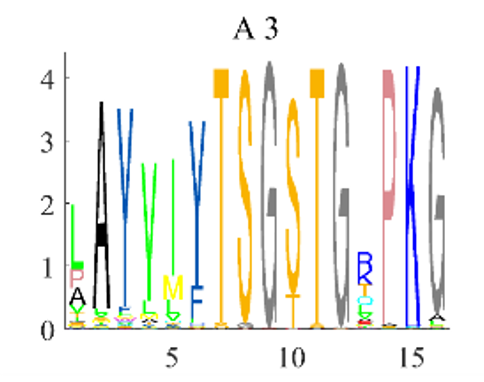

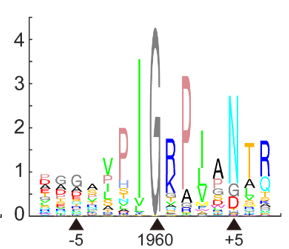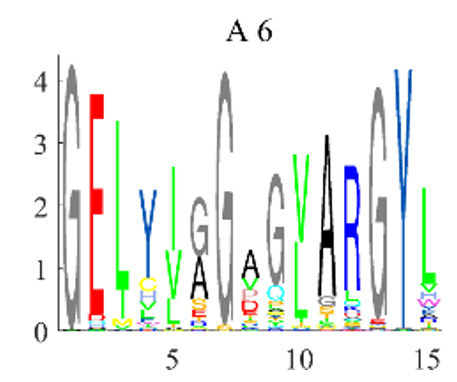

% use only active As/ or esle, use the "good r list"
activerlist=find(cEK_regions.fateid>1);

progresslist=(1:0.5:10)';
combined_types=[
    [Atype*ones(size(progresslist)),progresslist];
    Ttype,0.5;
    Ttype,1];


dtype=Atype;
mlist_firstmotif=find(ismember(motif_struct.region_id,activerlist) & ismember(motif_struct.motifid_mat_list,[dtype,1],'rows'));
loc_firstmotif=find(ismember(combined_types,[dtype,1],'rows'));
motif_mats=zeros(length(mlist_firstmotif),size(combined_types,1)); % all motifs related to this one
badmlist=[];
for i=1:length(mlist_firstmotif)
    for j=1:size(combined_types,1)
        shouldbe_mid = mlist_firstmotif(i)+j-loc_firstmotif;
        if ismember(motif_struct.motifid_mat_list(shouldbe_mid,:),combined_types(j,:),'rows')
            motif_mats(i,j)=shouldbe_mid;
        else
            badmlist(end+1)=i;
        end
    end
end %for i=1:length(m_list)
motif_mats(badmlist,:)=[];

fprintf('use %d As for the result:\n',size(motif_mats,1))

use 65 As for the result:


second_olist=motif_struct.omains_id(motif_mats(:,2));
[~,~,mat_specificity]=unique(cEK_omains.specificity_id(second_olist));

lastlen=1;

motifid_mdist_mul_gap=[]; % alone the whole
tot_msa=[];
for m=1:size(motif_mats,2)
    m_mat=motif_mats(:,m);
    
    thism_type=combined_types(m,:);
    
    motifloc=find(ismember(motif_struct.uni_motifids,thism_type,'rows'));
    diststruct_mlist=motif_struct.motif_diststruct{motifloc}.mlist;
    diststruct_olist=motif_struct.motif_diststruct{motifloc}.olist;
    diststruct_distm=squareform(motif_struct.motif_diststruct{motifloc}.distline);
    diststruct_msa=motif_struct.motif_diststruct{motifloc}.msa;
    
    
        % only extract these in "good regions"
    diststruct_list_2_use=nan*zeros(size(m_mat));
    for i=1:length(diststruct_list_2_use) % hereya
        loc=find(diststruct_mlist==m_mat(i));
        if ~isempty(loc)
            diststruct_list_2_use(i)=loc;  % hereya   
        else
            error('seq not here');
        end
        diststruct_list_2_use(i)=loc;
    end % hereya
    
    
    % identity and length
    meanlen_toadd=mean(motif_struct.seqlen_aa(diststruct_mlist(diststruct_list_2_use)));
    
    %%%%% obtain mutual informations
   % calculate mutual information
    m_specificity=mat_specificity;%(loc_in_mmat);% hereya
    msa=diststruct_msa(diststruct_list_2_use,:);% hereya
    nanpercent=sum(msa=='-',1)/size(msa,1);
    
    %[value,order]=sort(nanpercent);nanthresh=max(0.5,value(ceil(meanlen_toadd)));
    %msa=msa(:,nanpercent<nanthresh);
    
    msa_num=aa2int(msa);
    msa_num(msa=='-'|msa=='*')=nan;
    
    %  fprintf('%f\t%f\t%f\n',nanthresh,size(msa,2),meanlen_toadd)
    
    mulinfor_list=zeros(1,size(msa_num,2));
    for s=1:size(msa_num,2)
        nonzerolist=find(m_specificity>0);
        
        [H1,H2,CH1_given2,CH2_given1,mulin]=ZL_Mulinfor_int(msa_num(nonzerolist,s),m_specificity(nonzerolist));
        mulinfor_list(s)=mulin;
    end
    
    [condiH_eachsite,totalH,meandist_eachsite]=ZL_MotifbyConveration(msa,'aa',[],0);
    
    
    addeddata=[m*ones(size(mulinfor_list));
        meandist_eachsite;
        mulinfor_list;
        nanpercent];
    motifid_mdist_mul_gap=[motifid_mdist_mul_gap,addeddata];
    
    
    tot_msa=[tot_msa,msa];
    
    
    lastlen=lastlen+meanlen_toadd;
end

figure;
hold on;
column_to_keep=find(motifid_mdist_mul_gap(end,:)<gapthresh);

% assign color
mulinfor_eachsite=motifid_mdist_mul_gap(3,column_to_keep);
colortable=flipud(colormap('parula'));
colornum=size(colortable,1);
mulinfor_colorid=max(1,min(colornum,round(colornum*(mulinfor_eachsite-min(mulinfor_eachsite))/(max(mulinfor_eachsite)-min(mulinfor_eachsite)))));

for i=1:length(column_to_keep)
    posi=column_to_keep(i);
    bh=bar(i,motifid_mdist_mul_gap(2,posi),1);
    bh.EdgeColor='none';
    bh.FaceColor=colortable(mulinfor_colorid(i),:);
end

% mark positions for motifs
for i=1:size(combined_types,1)
    mtype=combined_types(i,:);
    dtype=mtype(1);
    if abs(mtype(2)-round(mtype(2)))<0.1
        locs=find(motifid_mdist_mul_gap(1,column_to_keep)==i);
        
        
             
          textstr=[cEK_omains.domaintypelist{dtype},num2str(mtype(2))];
        
         colorcode=cEK_omains.colorcode(dtype,:);  
         
        ph=patch([locs(1),locs(end),locs(end),locs(1)],[0,0,-1,-1]*0.02,colorcode);
        ph.EdgeColor='k';
        text((locs(1)),-0.05,textstr)
        
    end
end



CSeq_A = seqconsensus(tot_msa(:,column_to_keep));
Gmotif='PIGRPIAN'

Gmotif = 'PIGRPIAN'

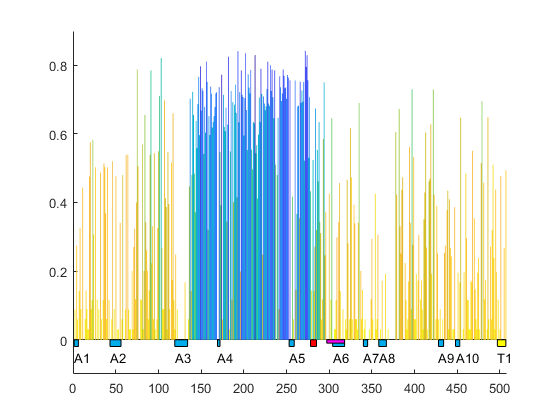

AlignStruct = localalign(CSeq_A, Gmotif);
Glogoposi=AlignStruct.Start(1,1):AlignStruct.Stop(1,1);


hold on;
locs=Glogoposi;
colorcode=[1,0,0];
ph=patch([locs(1),locs(end),locs(end),locs(1)],[0,0,-1,-1]*0.02,colorcode);
ph.EdgeColor='k';


ExtendedA6motif='LQPKGIYGELCIGGAGLARGYL';
AlignStruct = localalign(CSeq_A, ExtendedA6motif);
A6logoposi=AlignStruct.Start(1,1):AlignStruct.Stop(1,1);
locs=A6logoposi;
colorcode=[1,0,1];
ph=patch([locs(1),locs(end),locs(end),locs(1)],[0,0,-1,-1]*0.01,colorcode);

ylim([-0.1,0.9]);
set(gca,'ytick',0:0.2:1)

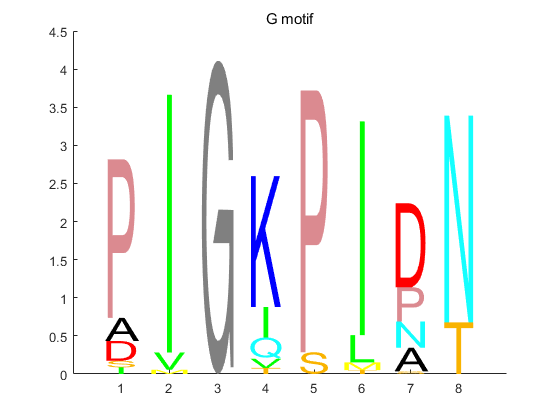




% output the G motif

figure;
SeqLogo_HRL(tot_msa(:,column_to_keep(Glogoposi)),'aa',aa_colormaping,letterclass,0);
set(gca,'xtick',1:length(Glogoposi))
%set(gca,'xticklabel',strsplit(num2str(Glogoposi)))
title('G motif')

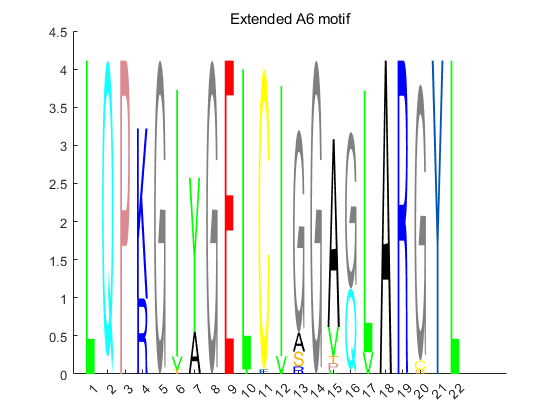



figure;
SeqLogo_HRL(tot_msa(:,column_to_keep(A6logoposi)),'aa',aa_colormaping,letterclass,0);
set(gca,'xtick',1:length(A6logoposi))
%set(gca,'xticklabel',strsplit(num2str(A6logoposi)))
title('Extended A6 motif')

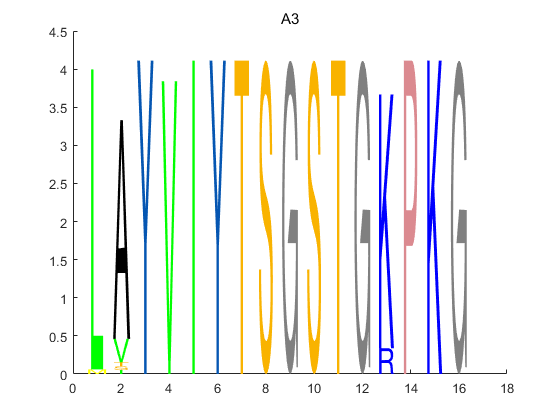

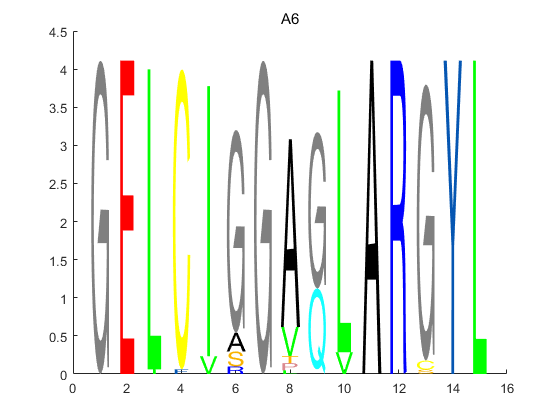



% output A3 and A6
for i=1:size(combined_types,1)
    mtype=combined_types(i,:);
    dtype=mtype(1);
    if dtype==Atype && ismember(mtype(2),[3,6])
        locs=find(motifid_mdist_mul_gap(1,column_to_keep)==i);
        figure;
        SeqLogo_HRL(tot_msa(:,column_to_keep(locs)),'aa',aa_colormaping,letterclass,0);

        title([cEK_omains.domaintypelist{dtype}, num2str(mtype(2))]);
    end
end


locs=292:299

locs =    292   293   294   295   296   297   298   299
